%生成一个四阶魔方阵，并将1，5，9个元素替换为naN,求替换后的各列向量标准差
clear all
clc
M=magic(4)%生成魔方

M =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


M([1 5 9])=[nan nan nan]%替换

M =    NaN   NaN   NaN    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


y=nanstd(M)%求解忽略nan后的标准差

y =     2.6458    3.5119    4.5092    5.4467


clear all
clc
x1=[5200 5056 561 6016 635 669 686 692 704 7007 711]

x1 =         5200        5056         561        6016         635         669         686         692         704        7007         711


x2=[7013 7104 719 727 735 740 744 745 750 7076 777]

x2 =         7013        7104         719         727         735         740         744         745         750        7076         777


x3=[7086 7806 791 7904 821 822 826 834 837 8056 862]

x3 =         7086        7806         791        7904         821         822         826         834         837        8056         862


x4=[8703 879 889 9000 904 922 926 952 963 1056 10074]

x4 =         8703         879         889        9000         904         922         926         952         963        1056       10074


x=[x1 x2 x3 x4]%放到一个矩阵

x =         5200        5056         561        6016         635         669         686         692         704        7007         711        7013        7104         719         727         735         740         744         745         750        7076         777        7086        7806         791        7904         821         822         826         834         837        8056         862        8703         879         889        9000         904         922         926         952         963        1056       10074


[H,P,JBSTAT,CV]=jbtest(x)%进行峰度偏度检验

H = 1

P = 0.0218

JBSTAT = 8.0228

CV = 4.8466

%[H,P,JBSTAT,CV]=jbtest(x，alpha)在显著水平alpha下进行偏度峰度检验
%该公式返回三个其它输出，H=1则显著水平0.05下拒绝x服从正态分布假设，h=0则服从
%P为检验的p值，JBSTAT为检验统计量，CV为确定是都拒绝零假设的临界值

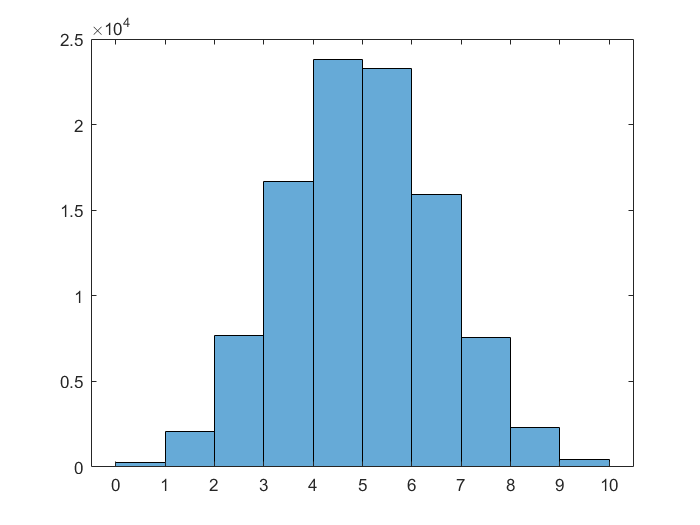

clear all
clc
x=binornd(10,0.45,100000,1);%该函数产生二项分布随机数。第一个参数为环数，第二个参数为概率，第三个参数为行数，第四个为列数
histogram(x,10)%输出直方图

%求poisspdf(x,lambda)参数为lambda的泊松分布的概率密度函数值
clear all 
clc
x=0:20

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


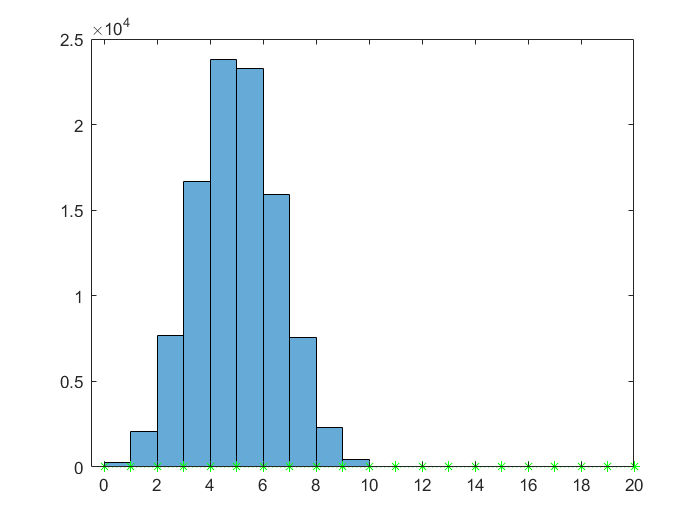

y1=poisspdf(x,2.5);
y2=poisspdf(x,5);
y3=poisspdf(x,10);
hold on
plot(x,y1,':r*')
plot(x,y2,':b*')
plot(x,y3,':g*')
hold off

a=0;
b=1:5;
r1=unifrnd(a,b)

r1 =     0.6112    1.4045    1.9922    1.5149    3.6869


r=normrnd(10,0.4,[2,4])

r =     9.4792    9.2672    9.5734   10.9036
    9.8424    9.0843   10.5846    9.0464
